#### Pythagorean Triples

Pythagorean triples are sets of three positive integers$(a,b,c)$ that satisfy the Pythagorean theorem $a^2+b^2=c^2$. This theorem applies to right-angled triangles, stating that the square of the length of the hypotenuse (the side opposite the right angle) is equal to the sum of the squares of the lengths of the other two sides.

my notes :

**Euclid's formula** is a fundamental formula for generating Pythagorean triples given an arbitrary pair of integers *m* and *n* with *m* > *n* > 0. The formula states that the integers .to visualize (a subset of) all Primitive Pythagorean Triples up to a certain maximum hypotenuse, using the parameterization:

  a = m^2 - n^2

  b = 2*m*n

  c = m^2 + n^2

by using vectorized computations generates and plots (a subset of) all  Primitive Pythagorean Triples with c up to maxHypotenuse. The triple generated by Euclid's formula is primitive if and only if m and n are coprime and exactly one of them is even. 

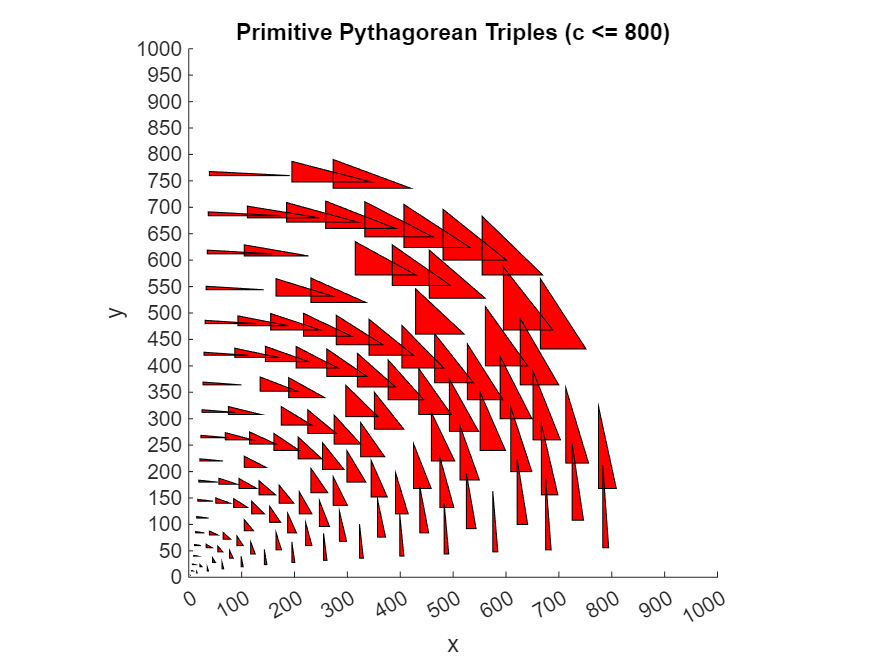

% Vectorized Primitive Pythagorean Triples Visualization

clear; clc; close all;

% 1. Setup figure
figure('Color','w');
hold on;
axis equal;
xlabel('x');
ylabel('y');
title('Vectorized Primitive Pythagorean Triples Visualization');

% Control axis limits and tick marks and  intervals
xlim([0 1000]);
ylim([0 1000]);
% The following lines customize the tick marks on the current axes:
%By calling gca, obtain a handle or a reference to the currently active axes
% XTick: Place tick marks on the x-axis 
% YTick: Place tick marks on the y-axis 
set(gca, 'XTick', 0:100:1000);
set(gca, 'YTick', 0:50:1000);


% 2. Define Parameters
maxHypotenuse = 800;    % Upper bound on c
scaleFactor   = 0.20;   % Offset factor for the triangle vertex

% Choose an upper bound for m such that m^2 + n^2 <= maxHypotenuse
% The floor function rounds a number down to the nearest integer
% We use 'floor' here to ensure mMax is an integer
mMax = floor(sqrt(900));
% using sqrt(900) = 30 as a fixed demonstration value


% 3. Generate all (m, n) pairs in one shot

% Here, we want to generate all possible pairs (m, n) in the specified range
% in a single operation The 'meshgrid' function takes two vectors and 
% produces two matrices (M and N) of the same size. Each position (i, j) 
% in these matrices corresponds to one combination of the input vectors:
%
%   M(i, j) = the j-th value from the first input vector
%   N(i, j) = the i-th value from the second input vector
%
% In this case, we pass 2:mMax as the first vector and 1:mMax as the second,
% giving us a full "grid" of (m, n) pairs over that range. This results in
% an mMax-by-mMax set of pairs for vectorized processing later on.

[M, N] = meshgrid(2:mMax, 1:mMax);

% We only consider pairs where n < m
validMask = (N < M);

% 4.Filter for Primitive Triples gcd(M, N) must be 1 (coprime), and (m - n) must be odd
G       = gcd(M, N);                
oddMask = (mod(M - N, 2) == 1);

% Combine conditions
validMask = validMask & (G == 1) & oddMask;

% 5. Compute (a, b, c) for all valid (m, n)
A = M.^2 - N.^2;      % a = m^2 - n^2
B = 2.*M.*N;          % b = 2*m*n
C = M.^2 + N.^2;      % c = m^2 + n^2

%6. Extract just the valid ones

% 'A', 'B', and 'C' were computed for all (m, n) pairs, including invalid ones
% 'validMask' is a logical array that marks only the valid (m, n) positions
validA = A(validMask);
validB = B(validMask);
validC = C(validMask);

%  Filter out any whose c exceeds maxHypotenuse
cMask  = validC <= maxHypotenuse;
validA = validA(cMask);
validB = validB(cMask);
validC = validC(cMask);

% At this point, validA, validB, validC are column vectors of the same length
% numTriples : how many valid triples we have
% which is the number of elements in, validA.
numTriples = length(validA);

% 7. Build the vertex arrays (X, Y) for all triangles at once
%    We draw each triple as a small triangle whose vertices are:
%      (a, b), (a, b + a*scaleFactor), (a + b*scaleFactor, b).
%    We'll store them as Nx3 matrices: each row is one triangle, with 3 columns
%    for the x-coordinates (and similarly for y).

X = [ validA,                 ...  % 1st vertex x
      validA,                 ...  % 2nd vertex x
      validA + scaleFactor.*validB];  % 3rd vertex x

Y = [ validB,                            ...  % 1st vertex y
      validB + scaleFactor.*validA,      ...  % 2nd vertex y
      validB ];                               % 3rd vertex y
%or
%   xCoords = [a, a, a + b*scaleFactor];
%   yCoords = [b, b + a*scaleFactor, b];

% 8 Plot all triangles in a single call to 'patch'
%    'patch' represent each row of X, Y as one polygon of triangle by default
patch(X', Y', 'r', 'EdgeColor', 'k', 'FaceAlpha', 1);

% all primitive Pythagorean triples with c up to 800
%num2str converts numeric values to their string 
title(['Primitive Pythagorean Triples (c <= ' num2str(maxHypotenuse) ')']);